# Development of Output Error State Space Models

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India    

## Introduction

In the previous lesson, we have seen how to [obtain input-output data for model](matlab:open('./L01_Introduction_to_System_Identification.mlx')) identification. In linear system identification, the data is used to identify either discrete linear state-space models or transfer function models. Both these describe the system dynamics using difference equations. In this lesson we will learn how to obtain discrete linear state space models of the form 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)+\varepsilon \left(k\right)
\end{array}$  ----------(1)

using experimental data by treating elements of matrices $\Phi ,\Gamma ,C$ in equation(1) as unknowns. Here $x\in R^n$ represents state vector, $u\in R^m$ represents manipulated inputs, $y\in R^r$ represents the vector of measured outputs, and $\varepsilon \in R^r$ represents a combined error signal that comprises of measurement noise and approximation errors. In system identification literature this signal is referred to as ***output error***.  Note that this modeling approach does not make any attempt to develop a model for the output error. We consider the following two scenarios: 

- **Grey-box models: ** Structure of $\left(\Phi ,\Gamma ,C\right)$ is chosen using a mechanistic model for the system but the parameters are treated as unknown. These unknown parameters are then estimated using the experimental input-output data. Thus, a grey-box model uses **known physical equations** where possible and, as a consequence, the model states retain their physical meaning. 

- ** Black Box Models: **No attempt is made to impose any structure on $\left(\Phi ,\Gamma ,C\right)$.  These dynamic models (difference equations) are mathematical constructs developed directly from *historical input-output data.*These models are devoid of any elucidation of physical mechanisms governing the underlying system.  These models provide NO insight into internal working of system under consideration.

In either case, the models are valid over limited operating range covered by the training data set. Development process of these models is  much less time consuming  and comparatively easy. It also does not need services of a domain expert. In this lesson, we will learn about the various models and a framework for estimating parameters called as Prediction Error Methods (PEM). Let us begin by estimating a linear state-space model for the Quadruple Tank Process from input-output data. 

**Learning Objectives:**

- To obtain grey-box and a black-box state space model with output error structure from the experimental input-output data using system identification toolbox in MATLAB

## Grey Box Models 

Let us begin our journey into data driven model identification by assuming that we know the structure of the mechanistic for the system under consideration but we have either partial or no knowledge of the model parameters. To motivate development of grey-box models, we use use the Q-tank as an example. For [Quadruple Tank Process](matlab:open('../2.Quadruple_Tank_Dynamical_Model/L02_DynamicsofMVPRocess.mlx')), that we have studied earlier, there are four water levels in the four tanks which are the **four states of the plant**. Two of these states level in tank 1 and tank 2 are *measured* outputs. There are two inputs to the process, which are pump voltages 1 and 2. From this basic information, we can start with a known structure of the model. 

Here $x\left(k\right)$ corresponds to level perturbations in the four tanks, *u*(*k*) corresponds to pump voltages to pump 1 and 2 that feeds water in tank 1 and 2 directly. $y\left(k\right)$ corresponds to measured outputs (in volts), i.e. level sensor outputs that correspond to measured levels in Tank 1 and Tank 2. Thus,


$$x\left(k\right)=\left\lbrack \begin{array}{c}
h_1 \left(k\right)-h_{1,s} \\
h_2 \left(k\right)-h_{2,s} \\
h_3 \left(k\right)-h_{3,s} \\
h_4 \left(k\right)-h_{4,s} 
\end{array}\right\rbrack$$
        
$$u\left(k\right)=\left\lbrack \begin{array}{c}
v_1 \left(k\right)-v_{1,s} \\
v_2 \left(k\right)-v_{2,s} 
\end{array}\right\rbrack$$
    
$$y\left(k\right)=\left\lbrack \begin{array}{c}
\gamma_1 \;\left(h_1 \left(k\right)-h_{1,s} \right)\\
\gamma_2 \;\left(h_2 \left(k\right)-h_{2,s} \right)
\end{array}\right\rbrack$$


 Let us explore grey-box models for the Q Tank process by assessing the structure of these matrices. We start by assuming that there are only four states of the process corresponding to the four heights. Note that this is an assumption as we understand from the first-principles model. We already know the linearized discrete model structure as

$\Phi$** Matrix:**

- The level in tank 1 at the current instant depends on the levels in tank 1 and 3 and hence in the first row of matrix $\Phi$ we have two entries corresponding to $h_1 \left(k\right)$ and $h_3 \left(k\right)$

- The level in tank 2 at the current instant depends on the levels in tank 2 and 4 and hence in the second row of matrix $\Phi$ we has two entries corresponding to $h_2 \left(k\right)$ and $h_4 \left(k\right)$

- For tanks 3 and 4, the levels at instant  $k+1$ depend only on the corresponding levels at instant $k$, hence row 3 and 4 have a single element each.

$\Phi =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & \alpha_2  & 0\\
0 & \alpha_3  & 0 & \alpha_4 \\
0 & 0 & \alpha_5  & 0\\
0 & 0 & 0 & \alpha_6 
\end{array}\right\rbrack$   ------------(2a)

$\Gamma$ **Matrix: **

- Level 1 changes due to both the inputs hence two elements in  row 1

- Level 2 changes due to both the inputs hence two elements in  row 2 as well

- Levels in Tank 3 and 4 get affected due to input 2 and input 1 respectively. 

Thus the matrix is assumed to be as follows

   $\Gamma =\left\lbrack \begin{array}{cc}
\beta_1  & \beta_2 \\
\beta_3  & \beta_4 \\
0 & \beta_5 \\
\beta_6  & 0
\end{array}\right\rbrack$   ----------(2b)    

$C$ **Matrix: **

- Level 1 and Level 2 are measured using level sensors while level 3 and 4 are not measured. Now, when we use the sensor-transmitter systems for level measurements, we know the relationship between the measured outputs (Volts in this case) and the tank levels. Thus, we fix the C matrix to be 

$C=\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0 & 0 & 0\\
0 & 0\ldotp 5 & 0 & 0
\end{array}\right\rbrack$---------(2c)

Note: We are specifying the sparsity structure of matrices i.e. we know where zero and non-zero elements are based on prior knowledge of the system. 

Define parameter vector 

$\Theta ={\left\lbrack \begin{array}{cccccc}
\alpha_1  & \ldotp \ldotp \ldotp  & \alpha_6  & \beta_1  & \ldotp \ldotp \ldotp  & \beta_6 
\end{array}\right\rbrack }^T$  --------(3)

the grey-box model can be expressed as follows 

$\begin{array}{l}
x\left(k+1\right)=\Phi \left(\Theta \right)x\left(k\right)+\Gamma \left(\Theta \right)u\left(k\right)\\
y\left(k\right)=C\left(\Theta \right)x\left(k\right)+\varepsilon \left(k\right)
\end{array}$  ---------(4)

Here, the parameter vector is an unknown that needs to be estimated using experimental data. In fact, though we derived equation (4) starting from Q-Tank example, it also represents general form of a grey-box model for any system where the dimension of the state is fixed based on the number of ODEs in the mechanistic model and the local derivatives decide non-zero parameters in $\left(\Phi ,\Gamma ,C\right)$. 

A systematic way to arrive at such a grey-box model structure is by examining Jacobian matrices obtained through Taylor series expansion of a nonlinear ODE model. Consider a Lumped Parameter Model, where the state dynamics are given by 

   $\begin{array}{l}
\frac{\textrm{dX}}{\textrm{dt}}=f\left(X\left(t\right),U\left(t\right)\right)\\
Y\left(t\right)=g\left(X\left(t\right)\right)\;
\end{array}$ ---------(5)

where **f and g** are nonlinear maps and 

- $X\in R^n$ represents state variables

- $U\in R^{m} $ represents manipulated inputs 

- $Y\in R^{r}$ represents measured outputs.

Applying the multivariable Taylor series expansion $f\left(X\left(t\right),U\left(t\right),D\left(t\right)\right)$  in the neighborhood of equilibrium point $\left(X_s ,U_s ,Y_s \right)$, we can arrive at a linear ODE model 

 $\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{\textrm{dx}}{\textrm{dt}}={\left\lbrack \frac{\partial f}{\partial X}\right\rbrack }_{\left(\bullet \right)} x\left(t\right)+{\left\lbrack \frac{\partial f}{\partial U}\right\rbrack }_{\left(\bullet \right)} u\left(t\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;y\left(t\right)={\left\lbrack \frac{\partial g}{\partial X}\right\rbrack }_{\left(X_s \right)} x\left(t\right)\\
x\left(t\right)\equiv X\left(t\right)-X_s \;,\;\;\;u\left(t\right)\equiv U\left(t\right)-U_s \;\;\;\textrm{and}\;\;y\left(t\right)\equiv Y\left(t\right)-Y_s \;
\end{array}$ ------(6)

Now, under the assumption that inputs are piece-wise constant and the sampling interval is sufficiently small, we can derive an approximate discrete time model of the form (1) by using Euler integration as follows 

$x\left(k+1\right)=\left({I+T\left\lbrack \frac{\partial f}{\partial X}\right\rbrack }_{\left(\bullet \right)} \right)x\left(k\right)+\left(T{\left\lbrack \frac{\partial f}{\partial U}\right\rbrack }_{\left(\bullet \right)} \right)u\left(k\right)$ ------(7a)

$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;y\left(k\right)={\left\lbrack \frac{\partial g}{\partial X}\right\rbrack }_{\left(X_s \right)} x\left(k\right)+\varepsilon \left(k\right)$      ------(7b)

Since we do not know model parameters, we cannot compute matrices 

$\Phi =\left({I+T\left\lbrack \frac{\partial f}{\partial X}\right\rbrack }_{\left(\bullet \right)} \right)\;,\;\;\Gamma =\left(T{\left\lbrack \frac{\partial f}{\partial U}\right\rbrack }_{\left(\bullet \right)} \right)\textrm{and}\;\;C={\left\lbrack \frac{\partial g}{\partial X}\right\rbrack }_{\left(X_s \right)}$   ------(7c)

However, from the ODE model, we know which elements in $\left(\Phi ,\Gamma ,C\right)$ matrices are non-zero and that information is sufficient to derive the structure for the grey-box model. 

## Black-Box Models 

       If no prior system knowledge is introduced in parameterizing the linear model, then the model is referred to as a **black-box model**. Here, we can parameterize $\Phi ,\Gamma ,C$ as full or dense matrices without specifying the sparsity. The parameter vector $\Theta$ encompasses all elements of the system matrices.  

    The state space representation of a system is not unique. Consider a square non-singular matrix $\Psi$. Let us define a new state vector $\chi \left(k\right)$ as$\chi \left(k\right)=\psi \;x\left(k\right)\;\;i\ldotp e\ldotp \;x\left(k\right)=\psi^{-1} \chi \left(k\right)$.  Substituting for vector $x\left(k\right)$ in state space model (1), we can write 

$\begin{array}{l}
\Psi^{-1} \chi \left(k+1\right)=\Phi \left(\Psi^{-1} \chi \left(k\right)\right)+\Gamma u\left(k\right)\\
y\left(k\right)=C\left(\Psi^{-1} \chi \left(k\right)\right)+\varepsilon \left(k\right)
\end{array}$  ------(8)

or 

$\begin{array}{l}
\chi \left(k+1\right)=\left(\Psi \Phi \Psi^{-1} \right)\;\chi \left(k\right)+\left\lbrack \Psi \Gamma \right\rbrack u\left(k\right)\\
y\left(k\right)=\left\lbrack C\Psi^{-1} \right\rbrack \chi \left(k\right)+\varepsilon \left(k\right)
\end{array}$---------(9)

Defining new matrices

$\tilde{\Phi} =\left\lbrack \Psi \Phi \Psi^{-1} \right\rbrack$, $\tilde{\Gamma} =\Psi \Gamma$ and $\tilde{C} =C\Psi^{-1}$  ------(10)

the state dynamics in terms of transformed states can be expressed as follows 

$\begin{array}{l}
\chi \left(k+1\right)=\tilde{\Phi} \;\chi \left(k\right)+\tilde{\Gamma} u\left(k\right)\\
y\left(k\right)=\tilde{C} \chi \left(k\right)+\varepsilon \left(k\right)
\end{array}$-----(11)

Note that the state transition matrices of both state realizations have identical eigenvalues, i.e.,

$\det \left\lbrack \lambda I-\tilde{\Phi} \right\rbrack =\det \left\lbrack \lambda \Psi \Psi^{-1} -\Psi \Phi \Psi^{-1} \right\rbrack =\det \left(\Psi \left\lbrack \lambda \textrm{𝐼}-\Phi \right\rbrack \psi^{-1} \right)=\det \left\lbrack \lambda \textrm{𝐼}-\Phi \right\rbrack$-------(12)

It can also be shown that the steady state gain matrix does not change with the variable transformation, i.e. 

$G=C{\left\lbrack I-\Phi \right\rbrack }^{-1} \Gamma =\tilde{C} {\left\lbrack I-\tilde{\Phi} \right\rbrack }^{-1} \tilde{\Gamma}$ ------(13)

The proof of equation (13) is left to the reader as an exercise. Since matrix a square invertible matrix, $\psi$ can be chosen in infinite possible ways, there are infinite possible state realizations for the system.

        Thus, if we associate vector$x\left(k\right)$ with states arising from a mechanistic model, then identification of state space matrices $\left(\tilde{\Phi} \left(\Theta \right),\tilde{\Gamma} \left(\Theta \right),\tilde{C} \left(\Theta \right)\right)$ with no structure imposed on parameter vector $\Theta$ can be viewed as identification of model (8) where $\chi \left(k\right)$ are some transformation of the original states. Note that vector $\Theta$ in this case consists of $n\times n+n\times m+r\times n$ unknown elements, that can be, in general, non-zero. The only information that we have used from the mechanistic model in this case is the order of the state vector, i.e. $\dim \left(x\right)=\dim \left(\chi \right)=n$. The transformed state vector $\chi \left(k\right)$ has, in general, no physical interpretation.  

## Model Parameter Estimation using Prediction Error Method (PEM)

Regardless of whether we identify black-box or grey-box model parameterization, parameters of the MIMO model structure can be obtained by different approaches. We will study one approach here by estimating plant outputs from the model structure and comparing them with that of the experimental data obtained. Parameter estimation is posed as an optimization problem where the error between these two signals is minimized. 

PEM  is a classical methods to estimate system parameters and exploit dynamical structure of the studied system. The dynamical structure could be a state space representation or a transfer function representation of the system. We present fundamentals of PEM in this sub-section. 

Let us assume that the input-output data consists of *N *data points. If $y\left(k\right)$ is the output data obtained from the experiments and, given an estimate of $\Theta =\tilde{\Theta}$, let $\hat{y} \left(k\right)=C\left(\tilde{\Theta} \right)\hat{x} \left(k,\tilde{\Theta} \right)$represent the predicted output from the state space model, then the parameters of the model $\Theta$ are estimated by minimizing the cost function that is a function of the prediction errors $\varepsilon \left(k\right)=y\left(k\right)-\hat{y} \left(k\right)$. A common cost function is the sum of squared prediction errors, 

$\sum_{i=1}^N {\varepsilon^2 }_i \left(k\right)=\sum_{i=1}^N {\left(\varepsilon \left(k\right)\right)}^T W\;\varepsilon \left(k\right)$  -------(14)

where $W$ is a positive definite matrix, which is typically selected as  $W$=${\left\lbrack \textrm{Cov}\left(v\left(k\right)\right)\right\rbrack }^{-1}$. 

    Here we illustrate how to find the parameters of state space model (4) using PEM.  Given set of manipulated inputs $U_N =\left\lbrace u\left(0\right),u\left(1\right),\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp u\left(N-1\right)\right\rbrace$, guess for $\Theta$ and initial state $\hat{x} \left(0\right)$, we can generate state sequence by recursively using difference equation,


$$\begin{array}{l}
\hat{y} \left(0\right)=C\left(\Theta \right)\hat{x} \left(0\right)\\
\hat{x} \left(1\right)=\Phi \left(\Theta \right)\hat{x} \left(0\right)+\Gamma \left(\Theta \right)u\left(0\right)\\
\hat{y} \left(1\right)=C\left(\Theta \right)\hat{x} \left(1\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Downarrow \\
\hat{x} \left(2\right)=\Phi \left(\Theta \right)\hat{x} \left(1\right)+\Gamma \left(\Theta \right)u\left(1\right)\\
\hat{y} \left(2\right)=C\left(\Theta \right)\hat{x} \left(2\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Downarrow \\
\hat{x} \left(3\right)=\Phi \left(\Theta \right)\hat{x} \left(2\right)+\Gamma \left(\Theta \right)u\left(2\right)\\
\hat{y} \left(3\right)=C\left(\Theta \right)\hat{x} \left(3\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Downarrow \\
\ldotp \ldotp \ldotp \ldotp \ldotp =\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp 
\end{array}$$


Define prediction error, $\varepsilon \left(k\right)=y\left(k\right)-\hat{y} \left(k\right)$, estimates of $\Theta$ and initial state $\hat{x} \left(0\right)$ can be obtained  by solving optimization problem 

$\begin{array}{l}
\left(\hat{\Theta} ,\hat{x} \left(0\right)\right)=\min_{\Theta ,\hat{x} \left(0\right)} \sum_{k=0}^N {\varepsilon \left(k\right)}^T W\varepsilon \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;s\textrm{ubject}\;\textrm{to}\\
\hat{x} \left(k+1\right)=\Phi \left(\Theta \right)\hat{x} \left(k\right)+\Gamma \left(\Theta \right)u\left(k\right)\\
\varepsilon \left(k\right)=y\left(k\right)-C\left(\Theta \right)\hat{x} \left(k\right)\\
\;\textrm{for}\;\;\;k=0,1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp N-1
\end{array}$     --------(15)

When a grey-box model is identified, it is possible to incorporate constraints that arise from physical considerations. For example, in the quadruple tank case, we know that all the elements of $\Gamma \;\textrm{and}\;C$ matrices are positive. We can impose constraints arising from signs of elements in the steady state gain matrix, and so on. This constraint can be explicitly included in the optimization formulation. 

The problem of identifying parameters of black-box model (11) can be formulated in an analogous manner as follows 

$\begin{array}{l}
\left(\hat{\Theta} ,\hat{\chi} \left(0\right)\right)=\min_{\Theta ,\hat{x} \left(0\right)} \sum_{k=0}^N {\varepsilon \left(k\right)}^T W\varepsilon \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;s\textrm{ubject}\;\textrm{to}\\
\hat{\chi} \left(k+1\right)=\Phi \left(\Theta \right)\hat{\chi} \left(k\right)+\Gamma \left(\Theta \right)u\left(k\right)\\
\varepsilon \left(k\right)=y\left(k\right)-C\left(\Theta \right)\hat{\chi} \left(k\right)\\
\;\textrm{for}\;\;\;k=0,1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp N-1
\end{array}$ ------(16)

Optimization problems (15) or (16) can be solved using

- **Gradient Descent:** A common optimization method where the parameters are updated in an iterative manner in the direction of the negative gradient of the cost function. This is also referred to as a first order method since only first derivative of cost function is used.

- **Other Optimization Algorithms:** Other optimization algorithms, such as the Newton method or Quasi-Newton methods use second order information (Hessian of the cost function). Methods such as Levenberg-Marquardt adaptively transition between first and second order methods.  

- **Sequential Quadratic Programming: **When we have inequality constraints, a constrained nonlinear programming method has to be used. 

Note that parameter estimation problem has to be solved using nonlinear optimization problem. It is well-known that even if we use high-quality data, the state-space matrices $\Phi ,\Gamma ,C,D$ cannot be uniquely determined by solving minimization problems, that is, there are infinite sets of state-space matrices that will provide the same value of cost function. 

## Black-Box and Grey-Box Model Identification for Quadruple Tank System 

We illustrate black-box and grey-box model development using the data obtained from the Quadruple Tank System simulations carried out in the previous lesson. Though we have introduced the grey-box models first and then discussed black-box models, we go in the reverse sequence while identifying the state space models. This is because the grey-box model identification function in the System Identification Toolbox requires a good initial guess of the model parameters. To generate such a guess, we first identify of model of the form (11) and use the identified model matrices to provide good initial guesses for the unknown parameters of the grey-box model (4). 

**Task 1:** **Select operating conditions and Load experimental perturbation data set**

Select operating point: **(1) Minimum Phase Operation (2) Non-minimum phase operation. **This will load the parameters specific to the operating point. 

clear all
close all

operating_pt=1; 

if operating_pt==1
    load QTank_Expt_Data_MinPhase
else
    load QTank_Expt_Data_NonMinPhase
end 
   

**Task 2: Create** **data object for System Identification toolbox. **Use MATLAB command,*** iddata***, to Create a data object to encapsulate the input/output data and  their properties.  

DAT = iddata(Y,U,Ts) to create a data object with output Y and input U and sample time Ts. Default Ts = 1. Use the inputs as **yk, uk** and **samp_T **and name the object as **iddatayu. **It is further split as **iddatayuE: **Data for model estimation and **iddatayuV: **Data for model validation

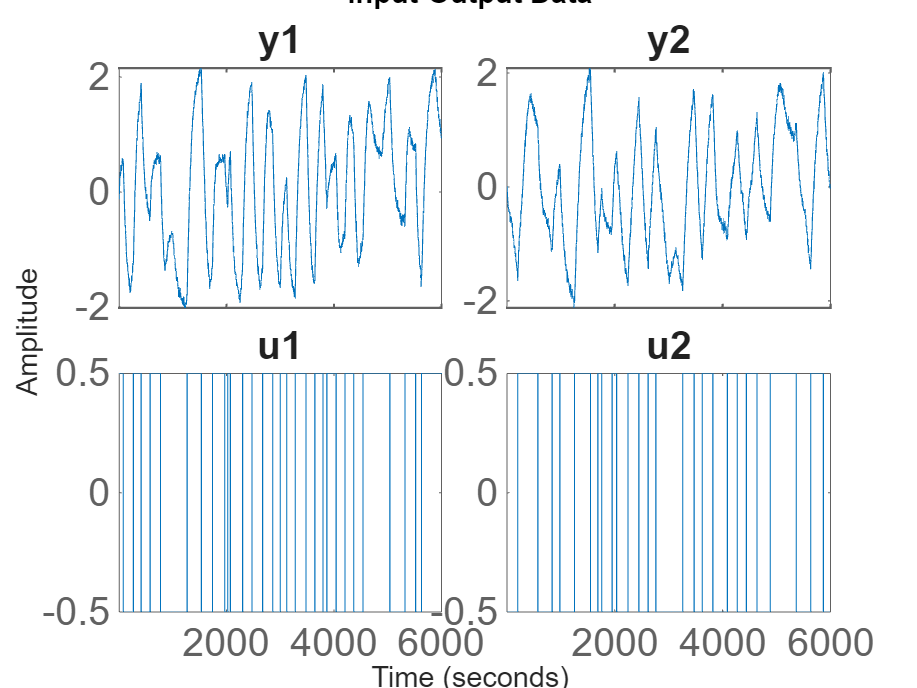

iddatayu=iddata(yk',uk',samp_T);
Est_Val_split =1500;% 1500% split into estimation and validation sets
iddatayuE = iddatayu(1:Est_Val_split); %Estimation Data
iddatayuV = iddatayu(Est_Val_split+1:end);  %Validation Data
idplot(iddatayuE)

**Task 3: Black-box Model identification ** 

[`sys`](https://in.mathworks.com/help/ident/ref/n4sid.html#mw_884b4d26-03ea-4cb7-8c3e-1c4afd29016c) `= pem(data, nx,'DisturbanceModel', 'none')` estimates a discrete-time state-space model `sys` of order `nx` using all the input and output signals in the identification data tt. Here `sys` is a model of the following form:


$$\begin{array}{l}
x\left(k+1\right)=\textrm{Ax}\left(k\right)+\textrm{Bu}\left(k\right)\\
y\left(k\right)=\textrm{Cx}\left(k\right)+\textrm{Du}\left(k\right)+\varepsilon \left(k\right)
\end{array}$$


*A*, *B*, *C*, *D,K *are state-space matrices. *u*(*t*) is the input, *y*(*t*) is the output, $\varepsilon \left(t\right)$ is the output error, and *x*(*t*) is the vector of `nx` states.

 Now let us create a model with name **BlackBox_model** using System Identification function ***pem*** with inputs as **iddatayuE** and order equal to 4. 

%%%% Black-Box Output Error STATE SPACE IDENTIFICATION  %%%%%%
% State space model of order 4 chosen based on prior knowledge 
n_st = 4 ; n_ip = 2 ; n_op = 2 ;  
BlackBox_model = pem(iddatayuE, n_st, 'DisturbanceModel', 'none')

BlackBox_model =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3        x4
   x1    0.9291    0.0125  -0.02518   0.07579
   x2   0.03268    0.9293   0.03914   0.07052
   x3   0.03114   0.07733    0.9325    0.1288
   x4  -0.05758  -0.02819  -0.07191    0.2264
 
  B = 
              u1         u2
   x1   0.008683  -0.003642
   x2  -0.005015   0.009261
   x3   0.002166   -0.01037
   x4   0.001882   0.006201
 
  C = 
             x1        x2        x3        x4
   y1     26.39     16.71     6.475    0.7374
   y2     12.97     26.72      9.12  -0.01927
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
  K = 
       y1  y2
   x1   0   0
   x2   0   0
   x3   0   0
   x4   0   0
 
Sample time: 4 seconds

Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: none
   Number of free coefficients: 32
   Use "idssdata

% Find simulated outputs using the identified black-box model 
y_blackbox_dev = sim(BlackBox_model, uk');
y_blackbox = y_blackbox_dev + Ys';

% Save model matrices for later use in controller synthesis 
idmod.phy= BlackBox_model.A;
idmod.gam = BlackBox_model.B;
idmod.C = BlackBox_model.C;
idmod.D = BlackBox_model.D;
idmod.L_mat = BlackBox_model.K; 

 if operating_pt==1
     save('QTank_MP_BlackBox_OE_SS.mat', 'idmod')
 else
     save('QTank_NMP_BlackBox_OE_SS.mat', 'idmod')
 end


** Task 4: Grey-box Model - Initialization of model parameters**

Here we define the structure that we would like to impose on the linear gray-box model.  Since, we have already obtained a 4-state black-box model using the identification command ***pem***, let us use the corresponding elements as the initial guess for the parameters of $\Phi$:

alpha(1) = BlackBox_model.A(1,1);
alpha(2) = BlackBox_model.A(1,3);
alpha(3) = BlackBox_model.A(2,2);
alpha(4) = BlackBox_model.A(2,4);
alpha(5) = BlackBox_model.A(3,3);
alpha(6) = BlackBox_model.A(4,4);

The Initial guess for the unknown parameter beta are obtained from the state space model B matrix obtained using the ***pem*** command in the previous step.

beta(1) = BlackBox_model.B(1,1);
beta(2) = BlackBox_model.B(1,2);
beta(3) = BlackBox_model.B(2,1);
beta(4) = BlackBox_model.B(2,2);
beta(5) = BlackBox_model.B(3,2);
beta(6) = BlackBox_model.B(4,1);

These initial guesses are stored in **initial_par **

%The initial guess for the Gray-box model parameters 

initial_par = mat2cell([alpha beta]',12,1);

Now we create the **idgrey** model.  An [`idgrey` model ](https://in.mathworks.com/help/ident/ref/idgrey.html)represents a linear system as a continuous-time or discrete-time state-space model with identifiable (estimable) coefficients. 

`sys` `= idgrey(odefun,parameters,fcn_type,extra_args,Ts)` creates a linear grey-box model `sys` with identifiable parameters. `odefun` specifies the user-defined function that relates the model parameters `parameters` to their state-space representation. `fcn_type` specifies whether the model is parameterized in continuous-time, discrete-time, or both.

Here **'myDiscreteGreyBoxModel_OE**' is the function where the model structure is described. **initial_par** is the initial parameter guess 'd' indicates the function returns discrete-time matrices.  [ ] means no extra arguments (aux) are passed and Ts_data sets the model's sample time.

Minit = idgrey('myDiscreteGreyBoxModel_OE', initial_par, 'd', [], samp_T);
y_Minit_dev = sim(Minit,uk');
y_Minit = y_Minit_dev + (Ys)';

** Task 5: Estimate the Grey-box model parameters**

Now we can estimate the model using [`sys`](https://in.mathworks.com/help/ident/ref/greyest.html#mw_dcbfe8ca-6ecd-4d16-96dc-dd023d03473b) `= greyest(`[`data`](https://in.mathworks.com/help/ident/ref/greyest.html#mw_69792c55-a9c7-49cc-b955-0debe3f59762)`,`[`init_sys`](https://in.mathworks.com/help/ident/ref/greyest.html#mw_6b96bc7b-bb67-4ba9-81fa-8d80700c84b3)`)` which estimates a linear grey-box model `sys` using the time-domain or frequency-domain data `data` and the initial model `init_sys`.

We use the previously generated identification data *iddatayuE* and the system *Minit* as inputs to greyest. The estimated model is saved as **Greybox_model.**

% Estimate the grey box model parameters
mygreyboxoptions = greyestOptions('Focus','simulation','Display','on',...
    'SearchMethod','auto'); 
%Set max no. of iterations for termination in case of failure to converge 
mygreyboxoptions.SearchOptions.MaxIterations = 1000;  
Greybox_model = greyest(iddatayuE, Minit,mygreyboxoptions)

Greybox_model =
  Discrete-time linear grey-box model defined by "myDiscreteGreyBoxModel_OE" function:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
            x1       x2       x3       x4
   x1   0.9394        0  -0.1624        0
   x2        0    0.959        0   0.1141
   x3        0        0   0.8497        0
   x4        0        0        0   0.8984
 
  B = 
            u1       u2
   x1   0.3257  0.01569
   x2  0.00999   0.2458
   x3        0  -0.1556
   x4   0.1004        0
 
  C = 
        x1   x2   x3   x4
   y1  0.5    0    0    0
   y2    0  0.5    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
  K = 
       y1  y2
   x1   0   0
   x2   0   0
   x3   0   0
   x4   0   0
 
  Model parameters:
   Par1 = 
     0.9394
    -0.1624
      0.959
     0.1141
     0.8497
     0.8984
     0.3257
    0.01569
    0.00999
     0.2458
    -0.1556
     0.1004
 
 
Sample time: 4 seconds
  
Parameterization:
   ODE Function: myDiscreteGrey

The output y_greybox of the grey box model **Greybox_model** is obtained by simulating the model. 

% Find simulated outputs using the identified grey-box model 
y_greybox_dev = sim(Greybox_model,uk');
 y_greybox = y_greybox_dev + (Ys)'; 
 y_Minit = y_Minit_dev + (Ys)';

**Task 6: Save model matrices for future use.** 

 idmod.phy= Greybox_model.A;
 idmod.gam = Greybox_model.B;
 idmod.C = Greybox_model.C;
 idmod.D = Greybox_model.D;
 idmod.L_mat = Greybox_model.K ;

 if operating_pt==1
     save('QTank_MP_GreyBox_OE_SS.mat', 'idmod')
 else
     save('QTank_NMP_GreyBox_OE_SS.mat', 'idmod')
 end

**Task 7: Display simulated outputs **

Lets plot the model outputs and compare them with the measurements.

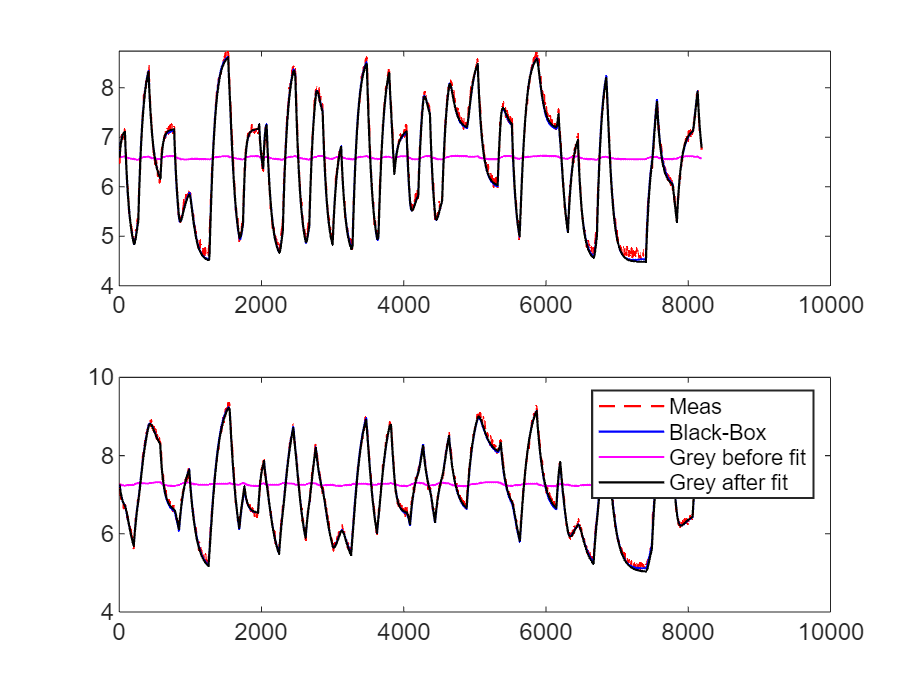

Yk = Ys + yk ;  % Create actual outputs from perturbation outputs

Set_Graphics_Parameters
 
figure(3)
subplot(2,1,1)
plot(kT,Yk(1,:)','r--') % raw measurements
hold on;
subplot(2,1,2)
plot(kT,Yk(2,:)','r--')
hold on;
figure(3)
% n4sid model output (this is black box)
subplot(2,1,1);hold on; plot(kT,y_blackbox(:,1),'b')
subplot(2,1,2);hold on; plot(kT,y_blackbox(:,2),'b'), 

%Grey box before fitting
figure(3)
subplot(2,1,1);hold on; plot(kT,y_Minit(:,1),'m')
subplot(2,1,2);hold on; plot(kT,y_Minit(:,2),'m'),

%Grey box after fitting
figure(3)
subplot(2,1,1);hold on; plot(kT,y_greybox(:,1),'k') %Fitted grey box
subplot(2,1,2);hold on; plot(kT,y_greybox(:,2),'k')
legend('Meas','Black-Box','Grey before fit','Grey after fit')

## Model Validation

One can define a measure for the prediction performance as a means of validating the identified model. One such measure used in Matlab is called  "%fit" and is based on the Normalized Root Mean Square of the Error and is defined as:


$$%\textrm{fit}=100\times \left(1-\frac{\left\|y_{\textrm{valid}} -\hat{\;y} {\;}_{\textrm{valid}} \right\|}{\left\|y_{\textrm{valid}} -\textrm{mean}\left(y_{\textrm{valid}} \right)\right\|}\right)$$


where *y* refers to the measurements in the validation dataset, $\hat{\;y}$ the corresponding model prediction and $\textrm{mean}\left(y\right)$, the mean of measurements in the validation dataset. Thus %fit provides us an idea of how much better would the prediction model compare relative to the naive strategy of using the mean of the validation dataset as the model response. The interested reader can access [http://www.mathworks.com/help/ident/ref/goodnessoffit.html](http://www.mathworks.com/help/ident/ref/goodnessoffit.html) to learn more about %fit. 

Matlab has a dedicated command called "[compare](https://in.mathworks.com/help/ident/ref/compare.html) " to evaluate %fits between various models by comparing them using a common validation data.

- `compare(`[`data`](https://in.mathworks.com/help/ident/ref/compare.html#mw_efc988ae-b2e6-4957-b0ec-5540930aac2d)`,`[`sys`](https://in.mathworks.com/help/ident/ref/compare.html#mw_644747c2-cc7b-44c6-953b-221f4b4684ac)`)` simulates the response of a single dynamic system model `sys` or an array of dynamic system models, and superimposes the response for each model over the plotted input/output measurement data contained in `data`. 

- The plot also displays the normalized root mean square (NRMSE) measure of the goodness of the fit between the simulated response and the output measurement data.

Lets compare performances of the above obtained linear discrete-time models (M_SS obtained using the subspace identification command ***pem*** and Greybox_model  obtained using PEM on the grey-box model) for a validation data set **iddatayuV**.

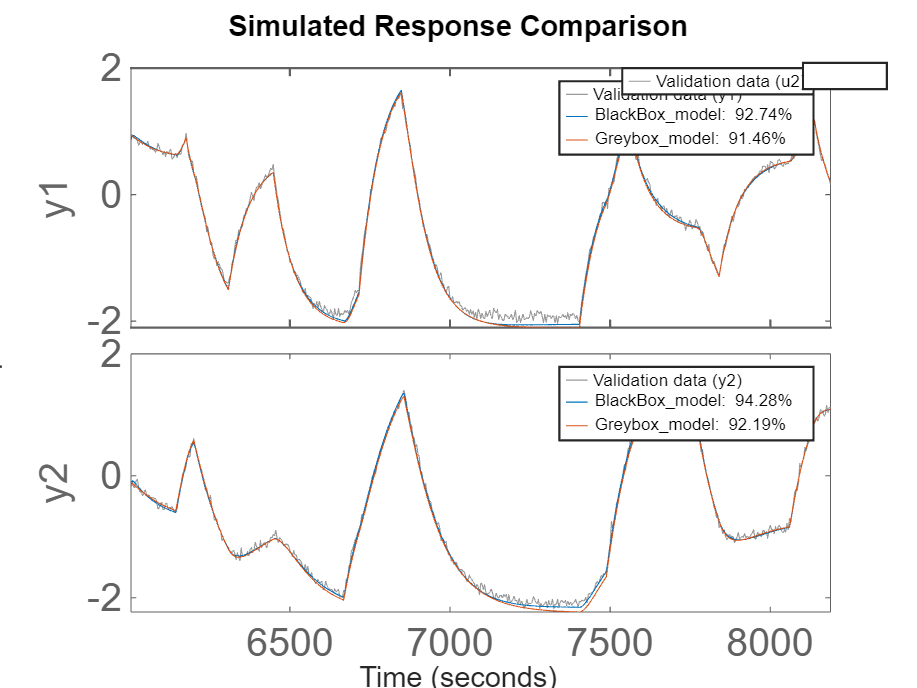

%%%%% COMPARE DIFFERENT MODELS ON VALIDATION SET 
%Lets compare performances on a validation set
figure(4)
compare(iddatayuV,BlackBox_model,Greybox_model)
ax = findall(gcf,'type','axes');
for k = 1:length(ax)
    lgd = legend(ax(k));
    if ~isempty(lgd)
        lgd.FontSize = 8;
        lgd.ItemTokenSize = [10 10];
    end
end

 For the purpose of comparison, we load the linear perturbation model obtained using linearization of the mechanistic model. Let us now check the step responses of the linearized model and the grey box model

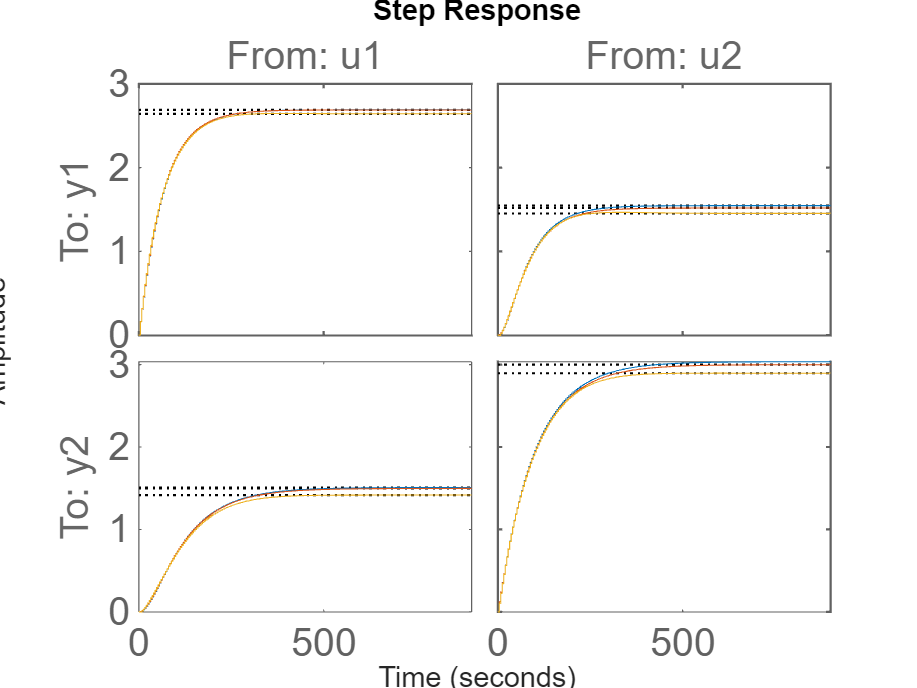

% Load linearized mechanistic model for the purpose of comparison

if operating_pt==1
    load QTank_MinPhase_Model
else
    load QTank_NonMinPhase_Model
end 

lin_mod=ss(QTank.phy, QTank.gama_u, QTank.C_mat, zeros(n_op,n_ip), samp_T);
step(lin_mod, Greybox_model, BlackBox_model)

Let us examine how close are the identified grey-box model matrices to the linearized mechanitic model. 


delta_phy = QTank.phy - Greybox_model.A 

delta_phy =     0.0005         0    0.3055         0
         0    0.0004         0   -0.0114
         0         0    0.0026         0
         0         0         0   -0.0033


delta_gam = QTank.gama_u - Greybox_model.B

delta_gam =    -0.0028   -0.0015
   -0.0034    0.0003
         0    0.3325
    0.0178         0


The difference can be attributed to (a) non-uniqueness of the solution obtained using nonlinear optimization and (b) effects of process nonlinearity present in the input-output experimental data. The step responses of all three models, however, are almost identical. Thus, both the identified models can be used for controller synthesis. 

Finally, let us compare the steady state gain matrices the identified models with that of the linearized mechanistic model. 

MechLin_gain = QTank.C_mat * inv( eye(n_st) - QTank.phy) * QTank.gama_u

MechLin_gain =     2.6898    1.5463
    1.5087    3.0356


BlackBox_gain = BlackBox_model.C * inv( eye(n_st) - BlackBox_model.A) * BlackBox_model.B

BlackBox_gain =     2.6417    1.4526
    1.4167    2.8955


Greybox_gain = Greybox_model.C * inv( eye(n_st) - Greybox_model.A) * Greybox_model.B

Greybox_gain =     2.6888    1.5178
    1.4980    2.9992


### **Summary of steps in Grey Box/ Black Box Model development **

To summarize, any data driven model identification exercise involves following steps 

- Planning of experiments for estimation of unknown model parameters and design of input perturbation sequences

- Carrying out open loop perturbation experiments   

- Selection of model structure 

- Estimation of model parameters from experimental data using optimization techniques 

- Model validation:  Dynamic prediction/simulation capabilities and steady state behavior 

## Conclusion

In this lesson, we have seen how a grey-box and a black-box state space model with output error structure model can be obtained from the experimental input-output data using system identification toolbox in MATLAB.  These models can be used for model based controller synthesis if we unmeasured disturbance modeling is not of interest. In the next lesson, we will study out to identify grey-box and black-box stationary Kalman filters (observers) from the experimental input-output data. 

## References

-  HouWang : Z.-S. Hou and Z. Wang, "From model-based control to data-driven control: Survey, classification and perspective," Information Sciences, vol. 235, pp. 3--35, 2013

- Shumway, R. H., Stoffer, D. S. Time Series Analysis and Its Applications  

- Ljung, L., Glad, T., Modeling of Dynamic Systems, Prentice Hall, N. J., 1994.

- Ljung, L., System Identification: Theory for Users, Prentice Hall, 1987. 

- Soderstorm and Stoica, System Identification, 1989.

- Astrom, K. J., and B. Wittenmark, Computer Controlled Systems, Prentice Hall India (1994).

- Franklin, G. F., Powell, J. D., and M. L. Workman, Digital Control Systems, Addison Wesley, 1990.